# Multivariate Gaussian: Joint, Marginal, and Conditional Pdfs

Note: this script reproduces the figures of the multivariate Gaussian in Section 3.8 of **Statistics for Chemical Engineers**. Victor Z UW-Madison, 2020 illustrate pdfs and cdfs for multivariate Gaussians

clc;  clear all; close all hidden; format short;

addpath('./Support')

## Model

specify mean and covariance

mu = [0 1];
Sigma = [1 -0.5; -0.5 1]; % anti-correlated

% peak density
fmu=1/((2*pi)*sqrt(det(Sigma)))

fmu = 0.1838


% compute the 95% confidence interval ellipse
alpha = 0.95; % confidence 
n = 2; % dimension of variable
A = inv(Sigma); % inverse covariance
b = chi2inv(alpha, n); % confidence level on 2d from chi2 distribution
[xe, ye, major, minor, bbox] = ellipse(A, b, 100, mu); % ellipse

% 95% marginal intervals
b2 = chi2inv(alpha, 1); % confidence level on 1d from chi2 distribution
xd2 = sqrt(b2.*diag(Sigma))'; % confidence interval on 1d
mbox = repmat(mu,5,1)+ [-xd2;  [xd2(1), -xd2(2)]; xd2; [-xd2(1), xd2(2)]; -xd2];

% evaluate probability density function in domain(-3,3 and -3,3)
nmesh = 100;
x1 = linspace(-3,3,nmesh); x2 = linspace(-2,4,nmesh); 
[X1,X2] = meshgrid(x1,x2); % create mesh
f = mvnpdf([X1(:) X2(:)],mu,Sigma); % pdf on mesh
f = reshape(f,length(x2),length(x1));

## Joint pdf and cdf

visualize joint pdf and cdf

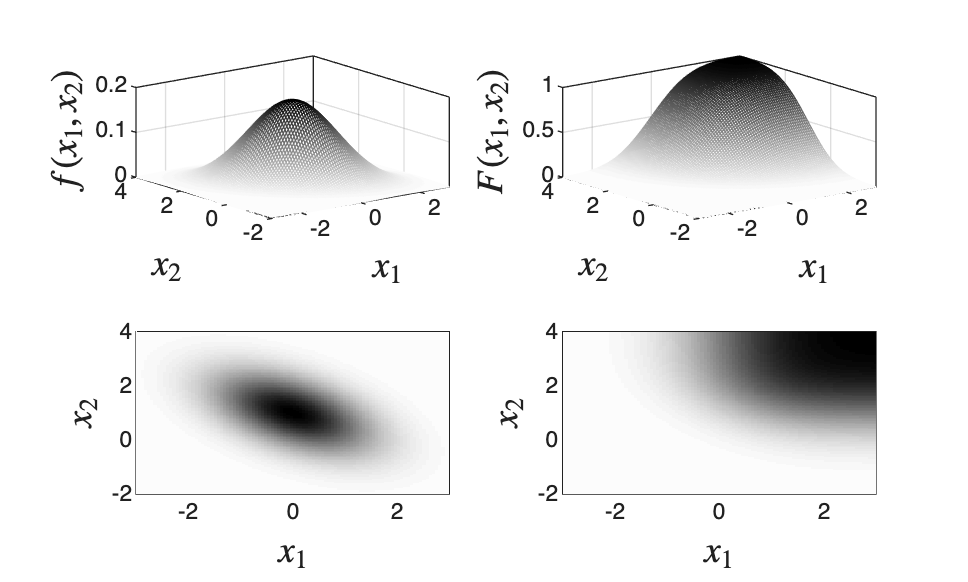

figure(1)
subplot(2,2,1)
c=linspace(0.99,0.0,64)';
C=[c,c,c];
mesh(x1,x2,f);
colormap(C);
axis([-3 3 -2 4 0 0.2])
box on
hold on
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14); 
zlabel('$f(x_1,x_2)$','Interpreter','latex','FontSize',14);

% evaluate cumulative probability density function in domain (-3,3 and -3,3)
F = mvncdf([X1(:) X2(:)],mu,Sigma); % pdf on mesh
F = reshape(F,length(x2),length(x1));

subplot(2,2,2)
c=linspace(0.99,0.0,64)';
C=[c,c,c];
mesh(x1,x2,F);
colormap(C);
axis([-3 3 -2 4 0 1])
box on
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14); 
zlabel('$F(x_1,x_2)$','Interpreter','latex','FontSize',14);

% visualize projection of 2D pdf
subplot(2,2,3)
imagesc('XData',x1,'YData',x2,'CData',f)
colormap(C);
grid on
axis([-3 3 -2 4])
box on
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14); 

% visualize projection of 2D cdf
subplot(2,2,4)
imagesc('XData',x1,'YData',x2,'CData',F)
colormap(C);
axis([-3 3 -2 4])
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14); 
box on
print -depsc -r1200 ch3_multigaussian.eps

## Marginal pdfs

visualize marginals

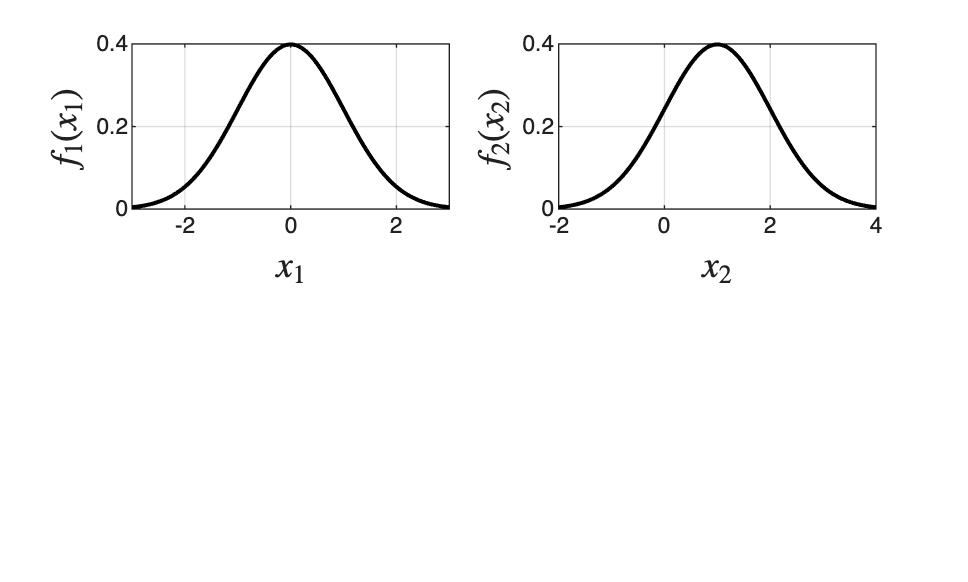

figure(2)
f1 = normpdf(x1,mu(1),sqrt(Sigma(1,1))); % pdf on mesh
subplot(2,2,1)
plot(x1,f1,'black','LineWidth',1.5);
grid on
axis([-3 3 0 0.4])
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$f_1(x_1)$','Interpreter','latex','FontSize',14);

f2 = normpdf(x2,mu(2),sqrt(Sigma(2,2))); % pdf on mesh
subplot(2,2,2)
plot(x2,f2,'black','LineWidth',1.5);
grid on
axis([-2 4 0 0.4])
xlabel('$x_2$','Interpreter','latex','FontSize',14); 
ylabel('$f_2(x_2)$','Interpreter','latex','FontSize',14);

print -depsc ch3_marginalgaussian.eps

## visualize conditionals

%X1|X2
x2p=1;
mu12=mu(1)+Sigma(1,2)*inv(Sigma(2,2))*(x2p-mu(2))

mu12 = 0

Sigma12=Sigma(1,1)-Sigma(1,2)*inv(Sigma(2,2))*Sigma(2,1)

Sigma12 = 0.7500


%X2|X1
x1p=1;
mu21=mu(2)+Sigma(2,1)*inv(Sigma(1,1))*(x1p-mu(1))

mu21 = 0.5000

Sigma21=Sigma(2,2)-Sigma(2,1)*inv(Sigma(1,1))*Sigma(1,2)

Sigma21 = 0.7500

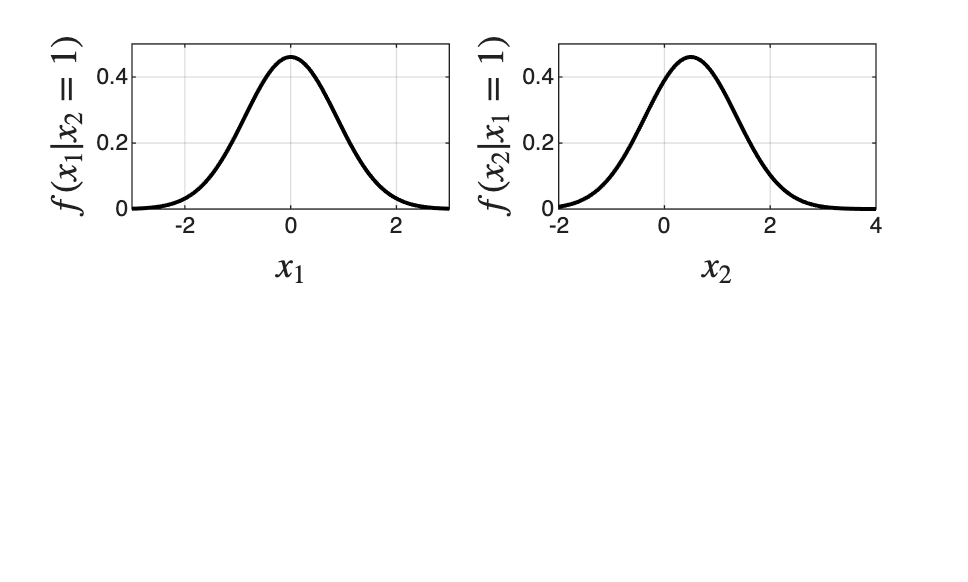


figure(3)
f12 = normpdf(x1,mu12,sqrt(Sigma12)); % pdf on mesh
subplot(2,2,1)
plot(x1,f12,'black','LineWidth',1.5);
grid on
axis([-3 3 0 0.5])
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$f(x_1|x_2=1)$','Interpreter','latex','FontSize',14);

f21 = normpdf(x2,mu21,sqrt(Sigma21)); % pdf on mesh
subplot(2,2,2)
plot(x2,f21,'black','LineWidth',1.5);
grid on
axis([-2 4 0 0.5])
xlabel('$x_2$','Interpreter','latex','FontSize',14); 
ylabel('$f(x_2|x_1=1)$','Interpreter','latex','FontSize',14);

print -depsc ch3_conditionalgaussian.eps

## Note

The marginal and conditional pdfs of a multivariate Gaussian are also Gaussian; conditioning shifts the mean and reduces the variance when the variables are correlated.